# Results

## Config

% add directory to search path
addpath('./libs');

path = './assets/results/test';
viz = Viz(path);

## Structure of Network

The network structure of the model which is shown as a *directed acyclic graph* (**DAG**).

Different parts of the model:

- Orange disk with label ***s*** indicates stimulus/input

- Orange disk with label ***r*** indicates expected response/output (this data is used just for training step)

- Green disks indicate the parameters (or unknows parameters which must be fine-tuned during the learning process)

- Red disk indicates the actual response/output

- Purple disk indicates the cost (the distance between the expected output and the actual output)

- Blue squares indicate layers (computational blocks). The ***+*** sign in their name show the sequential chain of them

- .

- Blue disks indicate the output of the layers

Abbreviations:

- s : Stimulus

- r : Response

- w: Weight/Kernel

- B : Bipolar

- A : Amacrine

- G : Ganglion

- c : Cost

- conv : Convolution

- relu : Rectified Linear Unit

- neg : Negation

- sum: Sum

- quadcost: Quadratic Cost

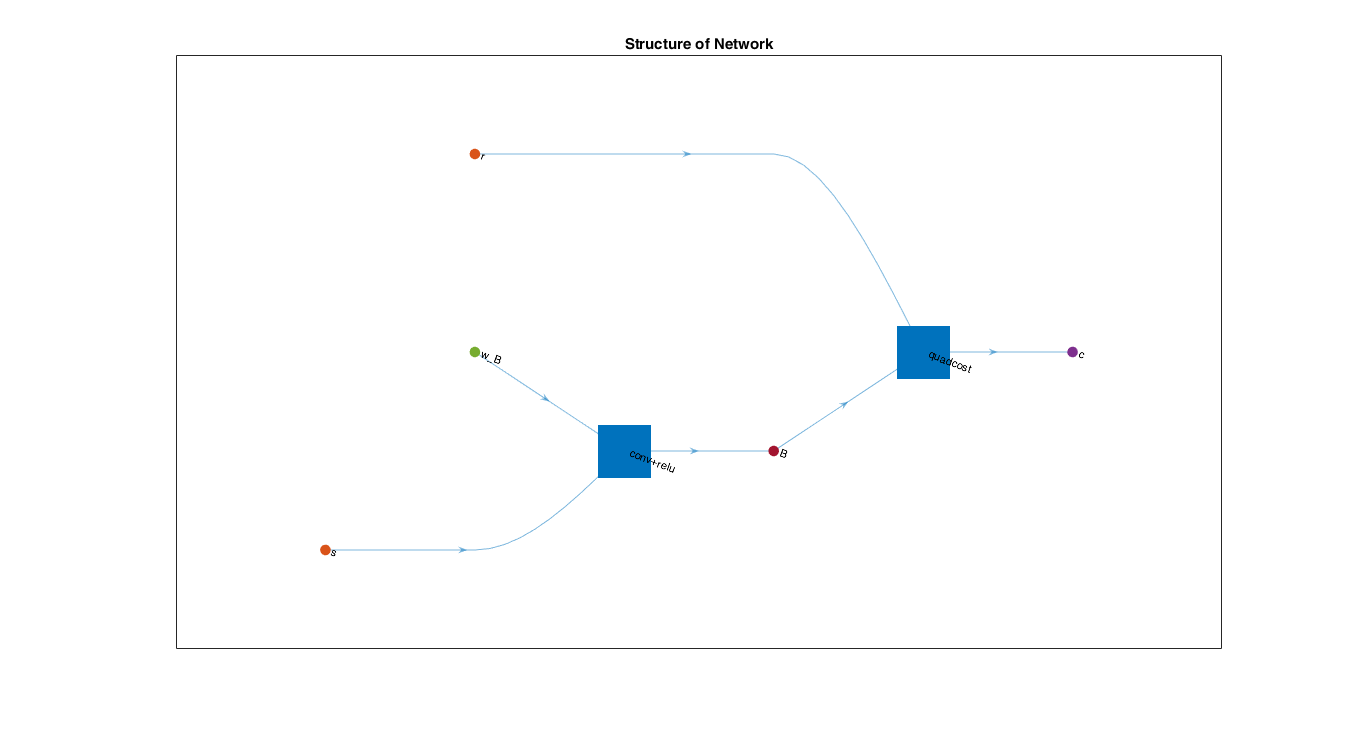

viz.plotNet();

## Data

These plots show the pairs of stimulae (blue) compared to their respective expected responses (orange). 50 of them are shown.

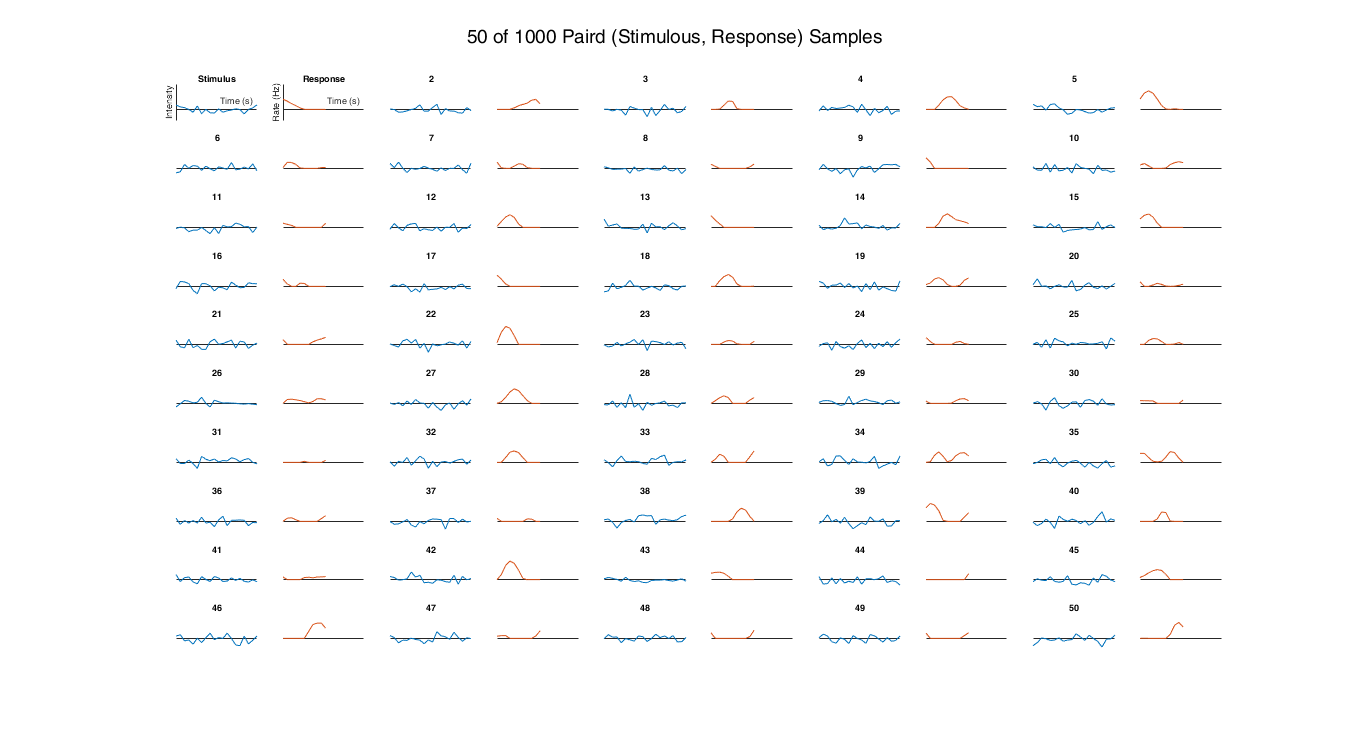

viz.plotData(1:50);

These plots show the pair of stimulae (blue) compared to its respective expected response (orange) for sample #1.

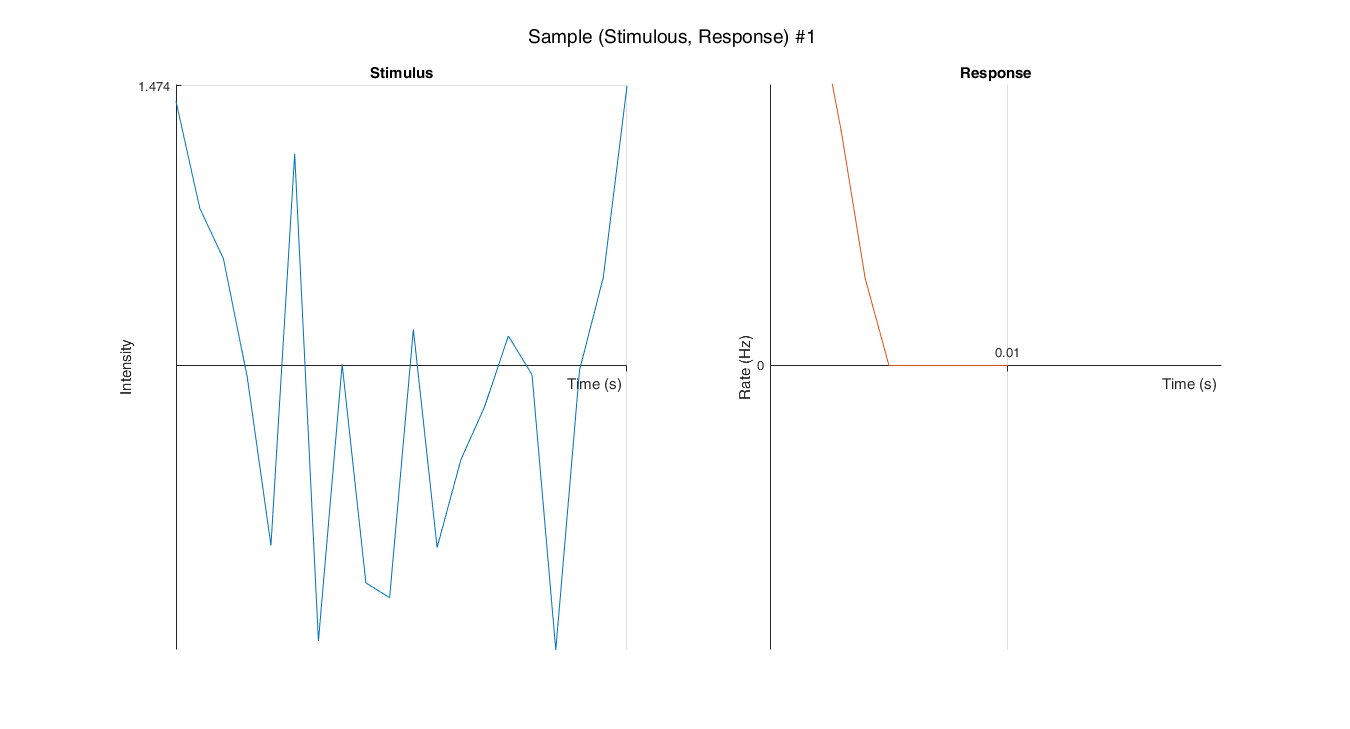

viz.plotSample(1);

These box plots show the instensity distribution in out stimulus and the frequency distribution of our response. The plot on the left plots the distribution of intensity of the stimulae, whereas the one on the right plots the distribution of frequency of the response.

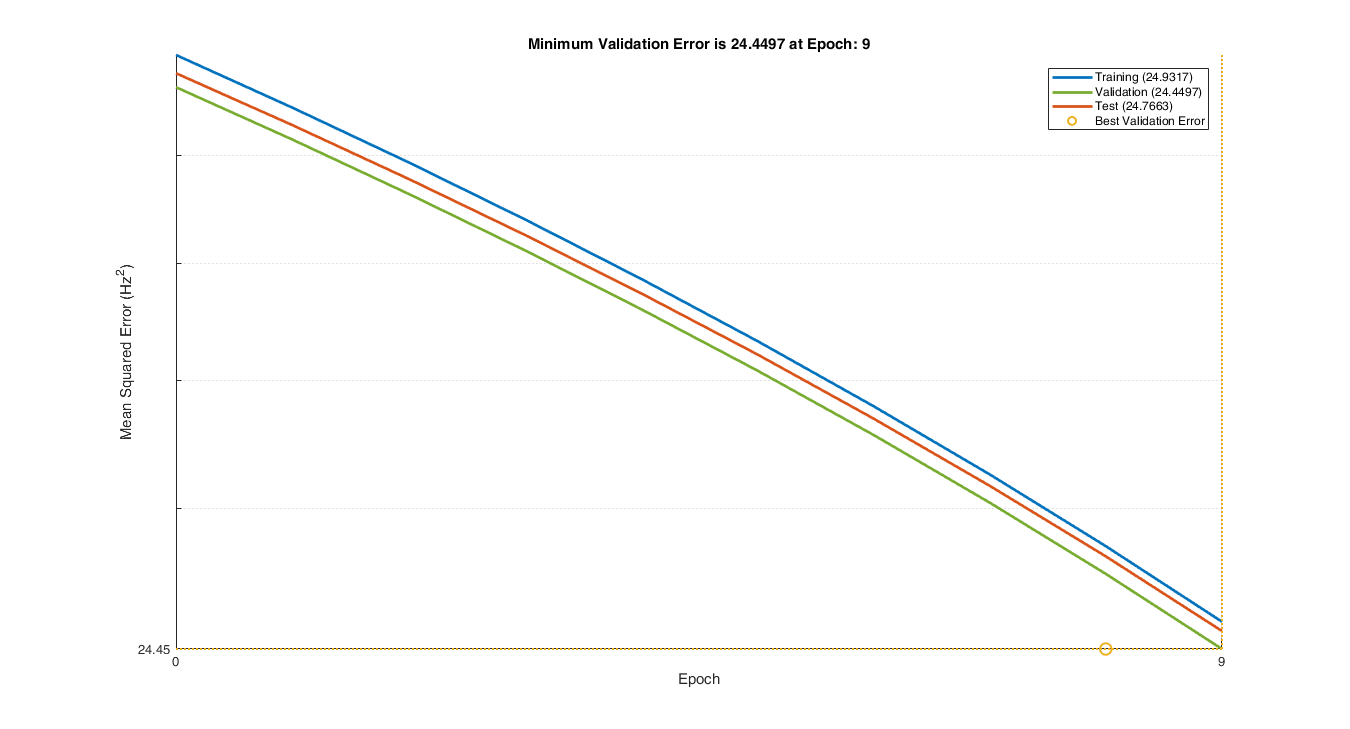

viz.boxplotData();

The color plot shows the distribution of how the data is divided into training, validation and testing. Training data displayed in blue, validation data, used to tune hyperparameters, shown in green, and test data, which is used to evaluate the network for the final test, shown in red.

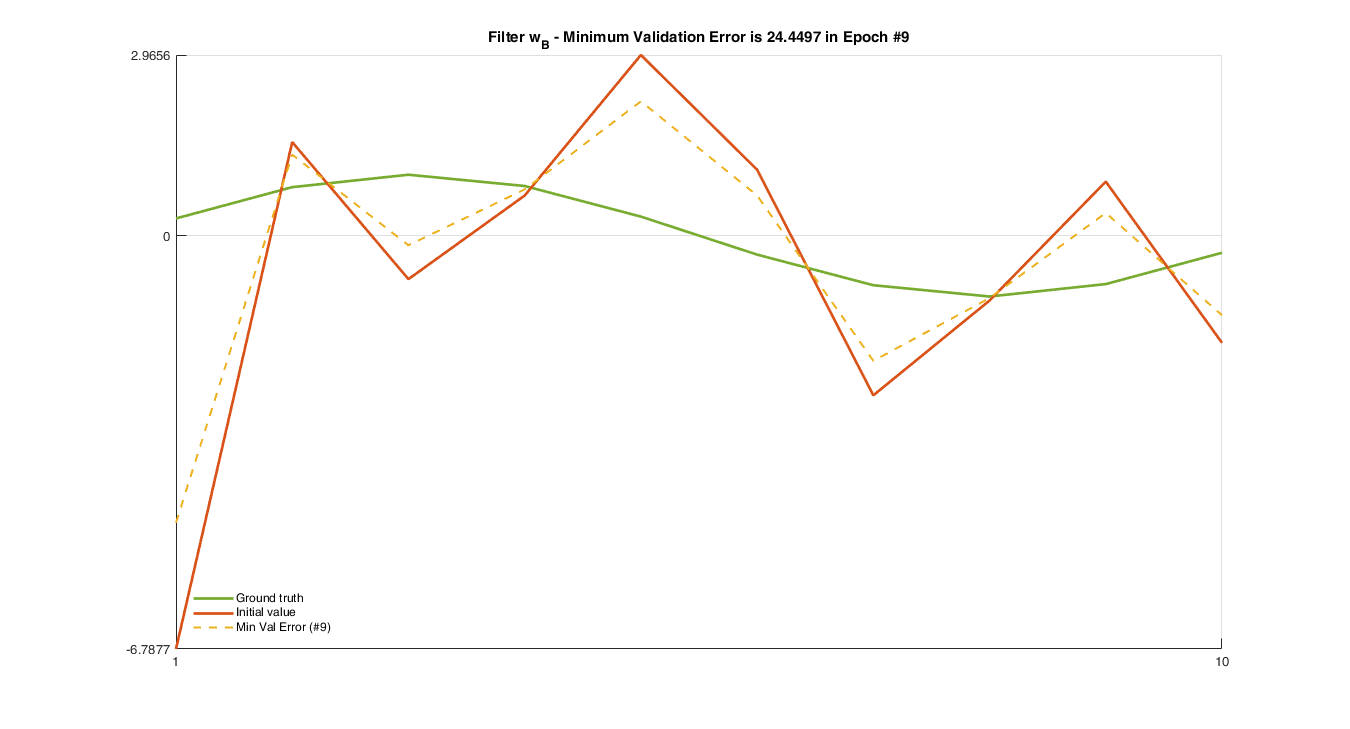

viz.boardplotData();

## Costs

Minimum validation plots: These plots show the error measured on the validation dataset after traning for a certain amount of epochs on the traning set. Training is shown in blue, validation in green and test in red. Minimum validation error is shown with a yellow circle. X axis marks which epoch the costs were calculated on and Y axis shows the mean square error.

Minimum difference of validation error plots: These plots plots show the change in costs between epochs. The maximum value is shown with a yellow circle. Training is shown in blue, validation in green and test in red. X axis marks which epoch the costs were calculated on and Y axis shows the first derivative of the mean square error, which is a measure of the change in costs between epochs.

Video path: '.\assets\results\model1.09-Apr-2018.14-29-01\vidoes\w_B.mp4'

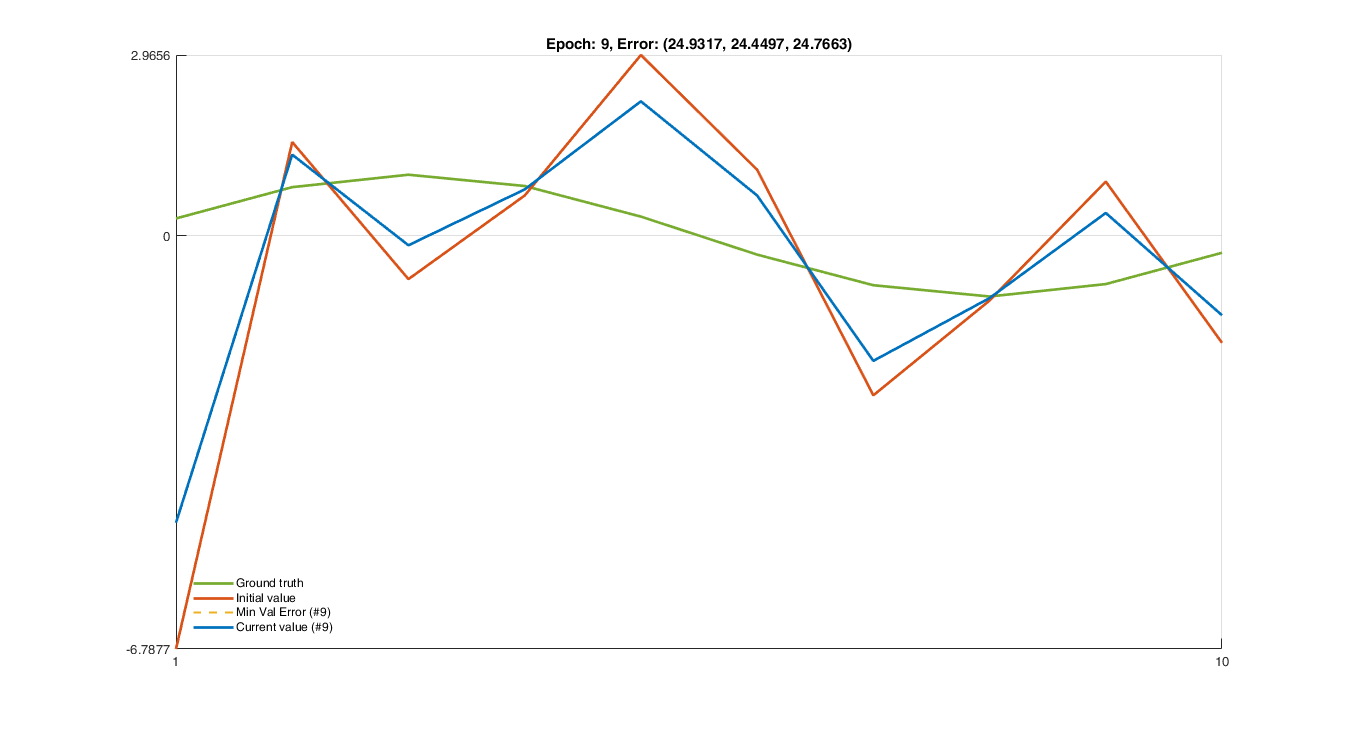

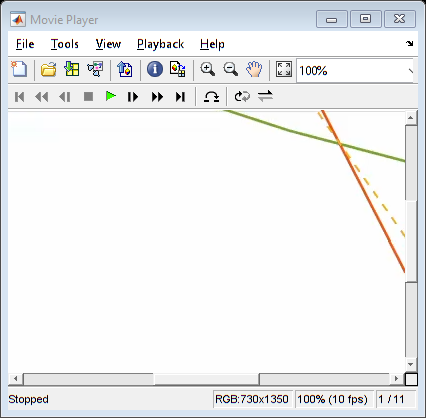

viz.plotCosts();

viz.plotCosts('diff');
viz.plotCosts([], 'linear');
viz.plotCosts('diff', 'linear');

## Filters

Shows the different parameter or weight vectors that are involved in the current network configuration.

viz.paramNames

These plots show the ground truth or expected weight vector values, along with their initial values when learning and their best results after learning.

viz.plotFilter();

Video sequence of how the weight vectors change throughout the learning process compared with the ground truth and initial values.

Learning history: Sequence of small plots of what the weight vectors look like for each epoch of learning.

viz.playFilterVideo();
viz.plotFilterHistory();